**Paer1-1:** Load data and Extract input and output variables from the data 

    Attribute Information:

-   column 1. mpg:           continuous

-   column 2. cylinders:     multi-valued discrete

-   column 3. displacement:  continuous

-   column 4. horsepower:    continuous

-   column 5. weight:        continuous

-   column 6. acceleration:  continuous

-  column 7. model year:    multi-valued discrete

-  column 8. origin:        multi-valued discrete

clear all;
close all;

%% Add code:
% complete the lines of code for data loading 

data = load('car_mpg.csv');



%Add code: extract horse power as input which is in column 4
x_input = data(:,4);


%Add code: extract mpg as target output

y_output = data(:,1);


**Part1-2**: Plot the data for the visualization :  Horse power  vs. mpg

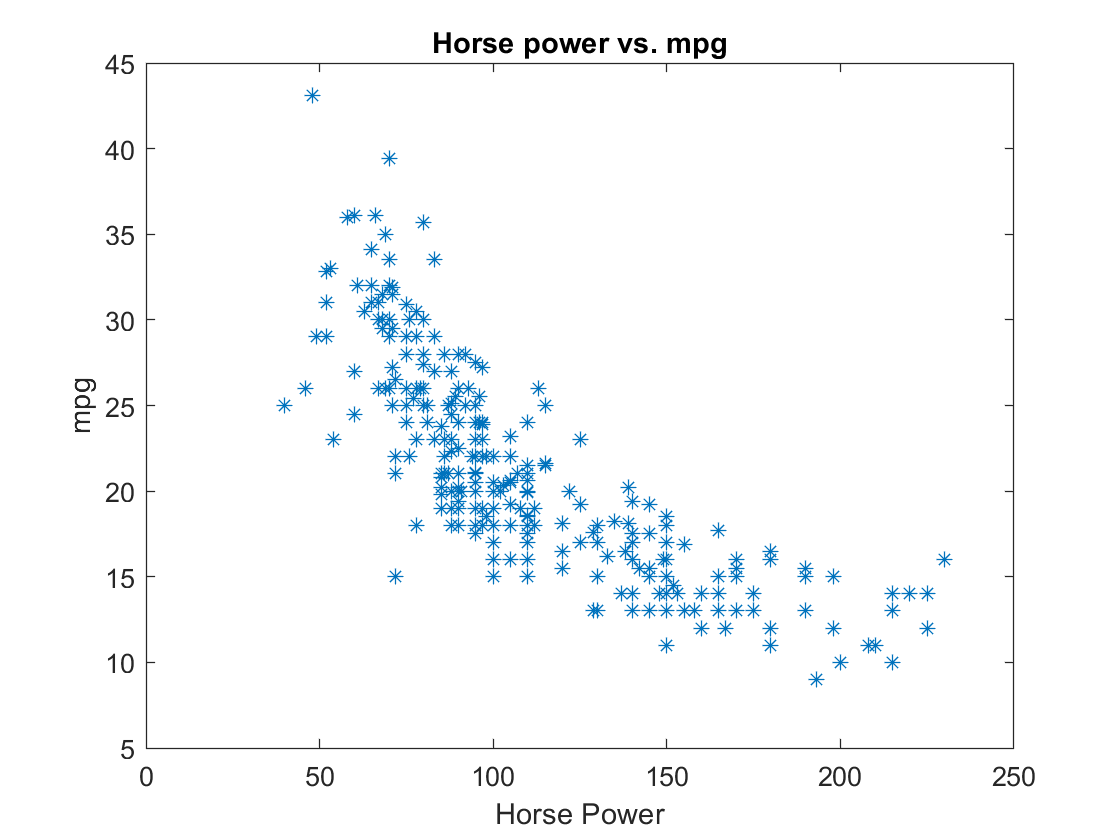

%% Add code:
% %add the lines of code for data visualization: plot of horse power vs. mpg
figure(1)

plot(x_input,y_output,'*'); xlabel('Horse Power'); ylabel('mpg'); title("Horse power vs. mpg")

**Part1-3**: Data Normalization : In machine learning, data normalization is a procedure that m**akes input features are in the similar ranges. **And another reason why data normalization is applied that  **Gradient descent converges much faster with feature scaling than without feature scaling. **

%% Add code:
% %add the lines of code for data normalization 
% Use the standardization method whcih uses the mean and the standard deviation of the feature. 

[num_features, num_labels] = size(x_input);
data_norm = (x_input - mean(x_input))./(std(x_input));


**Part1-4:** add an intercept term (Bias term) in the input matrix and Set the Learning rate and the number of iteration

%% Add code: 
% add a lines of code to add the bias term into the input matirx



x_0 = ones(300,1);
X = [x_0 data_norm];
alpha = 0.01;  %learning rate

iteration = 1000;

**Part1-5**: Find parameters using the gradient descent method 

%ADD code:
% complete lines of code for the gradient descent
k = 1;
Cost_J = zeros(iteration, 1);   %cost fucntion J
W = zeros(k+1,1) ;   % k features in put, w=(k+1)x1 by including  the intercept term 

size(W);
[M,n] = size(X);


for i = 1:iteration

    %predcition calculation 
    
    y_pred = X*W;
    
    
    %Error calculation 
  
    error = y_pred - y_output;
    
    
    
    %Partial derivatives calculation
    delta_W = (1/M)*(error'*X);
   
    
    
    % weight update
   
    W = W-alpha*delta_W';
   
    % Add code: save the cost J at each iteration i for the later plotting
    Cost_J(i) = (1/(2*M))*sum((error.^2));
    
end


figure(2);

%% Add code:
% %add the lines of code to plot the MSE cost convergence


**Part1-6**  Plot the MSE cost convergence graph

fprintf("Final Training MSE error %0.5g\nW0:%0.5g\nW1:%0.5g",Cost_J(iteration), W(1), W(2));

Final Training MSE error 7.1041
W0:20.798
W1:-5.0247

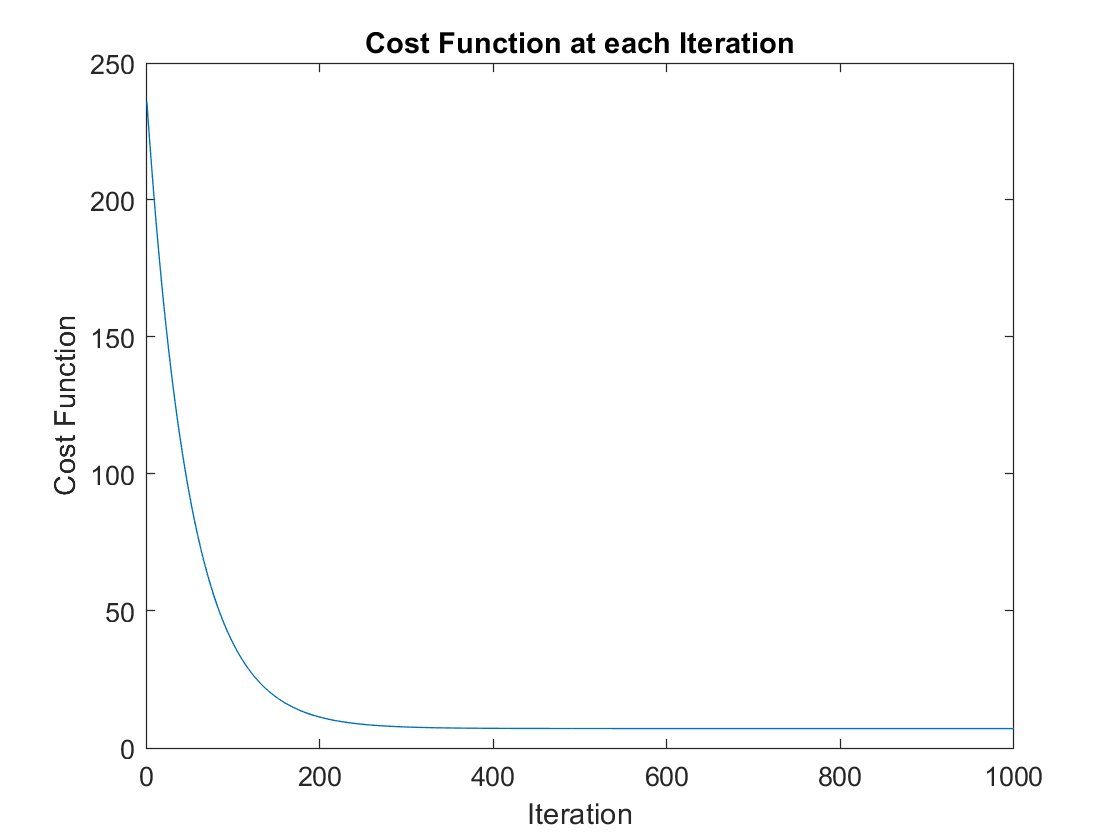

plot(Cost_J)
ylabel('Cost Function');
xlabel('Iteration');
title('Cost Function at each Iteration');

**Part1-7:** PLot the linear regression over the data

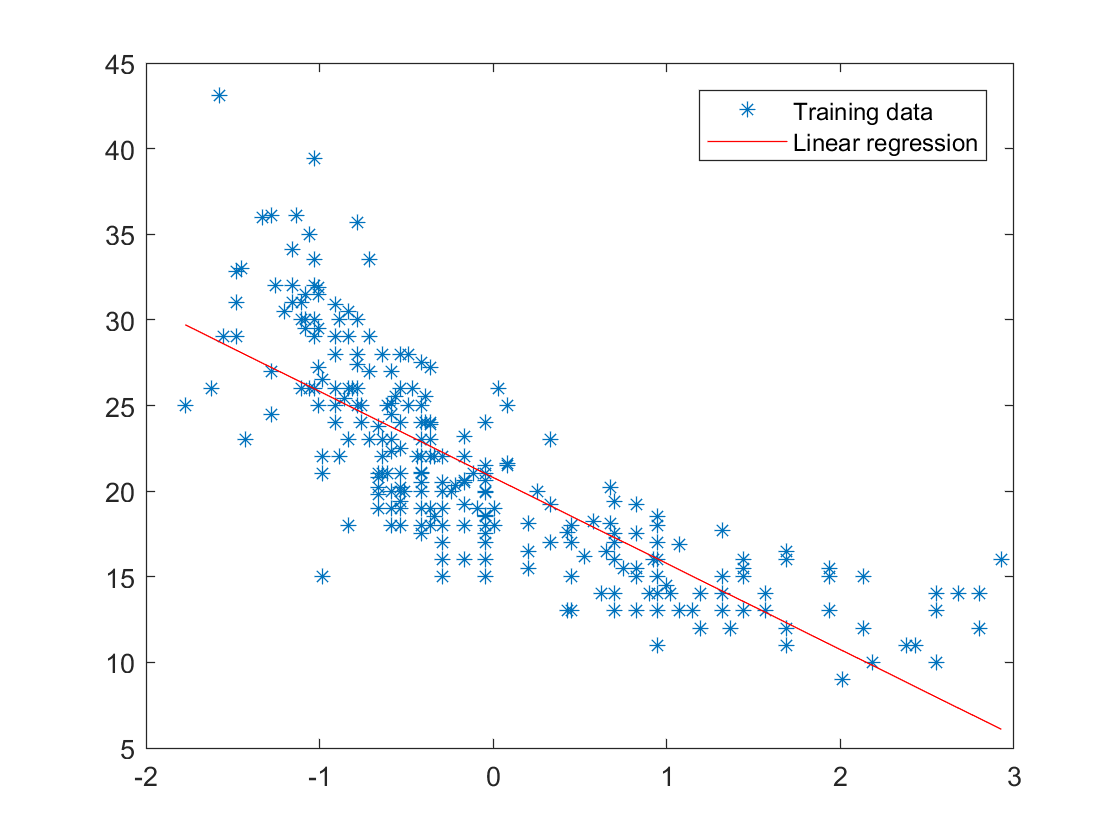

figure(1)

%% plot the horse power vs. mpg 

plot(data_norm,y_output,'*');

hold on; % keep previous plot visible

%% plot the horse power vs. predicted values. use '-' option inside plot()fucntion 

plot(data_norm, y_pred, '-r')


legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

Part1-8:**Test the prediction model with a new dataset**

%%% Add Code:
% file the lines of code for data loading and extracting input and output


% Load the testing data "car_mpg_testingData.csv"

test_file = load('car_mpg_testingData.csv');

%extract horse power as input which is in column 4

test_data = test_file(:,4);
%extract mpg as target output

target_output = test_file(:,1);
%Data normalization using the same mean and the same standard deviation calcualted with the training data
[M,n] = size(test_data);
Tdata_norm = (test_data - mean(x_input))./(std(x_input));
%Toutput_norm = (target_output - mean(target_output))/(std(target_output));
%add the bais term 
x_0 = ones(M,1);

X = [x_0, Tdata_norm];

%make a prediction for the test data

h = X*W;
%calculate the error

 error = h - target_output;
%calculate the MSE error for the testing data

MSE = (1/(2*M))*sum((error.^2));

fprintf("test MSE %0.5g", MSE);

test MSE 15.271




%{
%Personal -- Plot the test data on the linear regression line
figure(2)
plot(data_norm, y_pred, '-r')
hold on
plot(Tdata_norm, h, '*g')
hold on
plot(target_output, "*b")
legend('Linear Regression', 'Test Data', 'Target Output');
%}

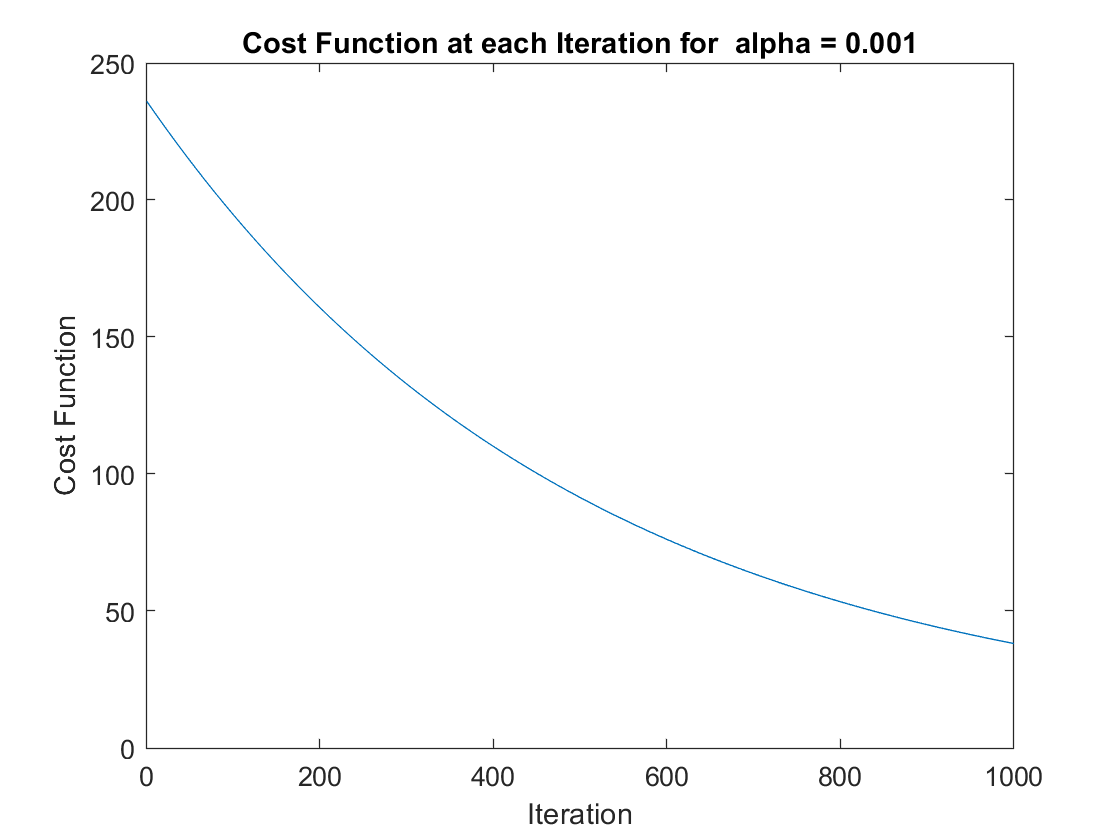

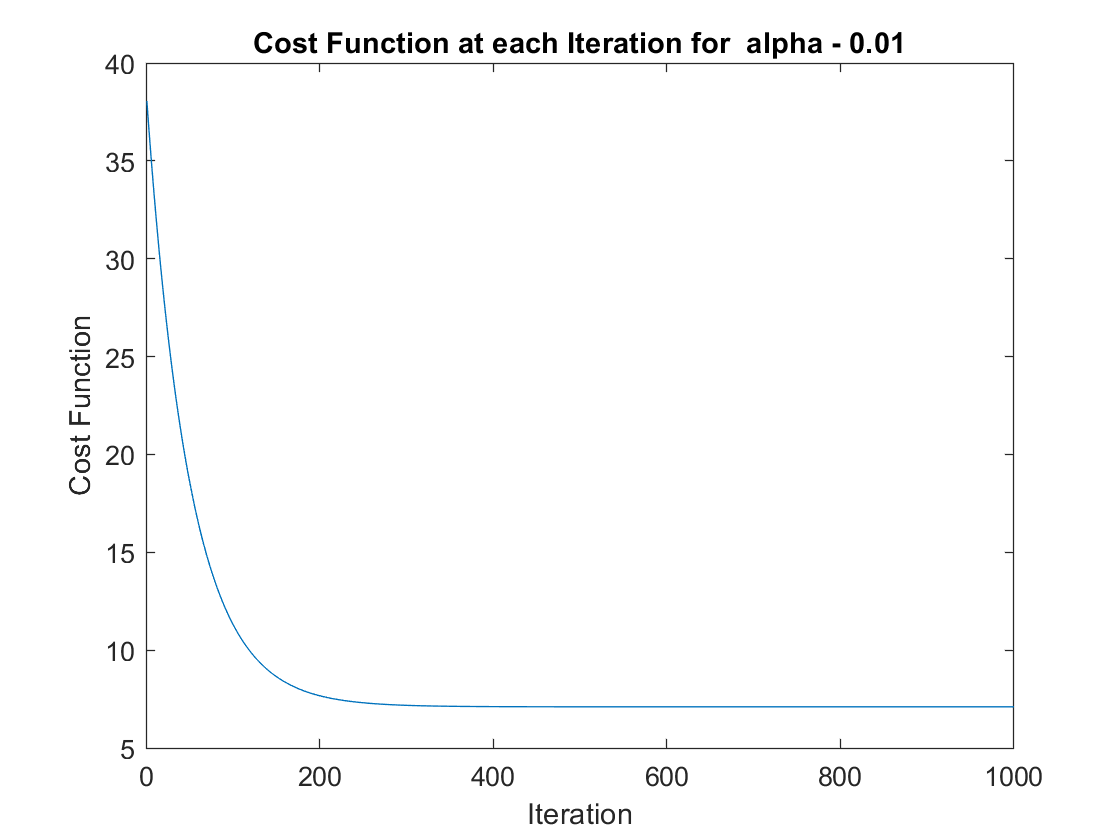

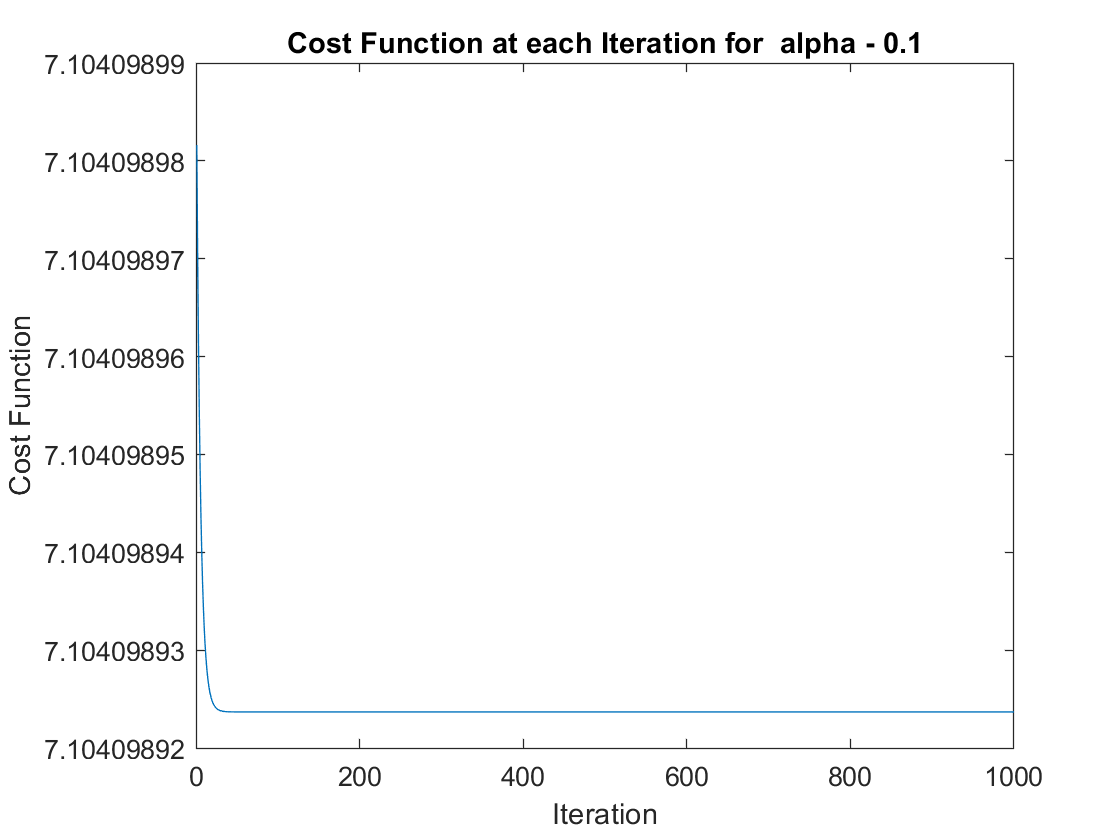

%{
Conduct an experiment with 3 different learning rates
alpha = 0.001,0.01,0.1

generate the MSE cost convergence plots with the 
different learning rates
write your observation on the effect of the learning rate in ML
%}

data = load('car_mpg.csv');
x = data(:,4);
y = data(:,1);
[M,n] = size(x);
x_norm = (x - mean(x))./std(x);

k = 300;
x_0 = ones(k,1);
X = [x_0 x_norm];
alpha = [0.001, 0.01, 0.1];  %learning rate

iteration = 1000;
Cost_J = zeros(iteration, 1);   %cost fucntion J
W = zeros(2,1);    % k features in put, w=(k+1)x1 by including  the intercept term 

size(W);
[M,n] = size(X);


for j = 1:3
    for i = 1:iteration
    
    %predcition calculation 
    
    y_pred = X*W;
    
    
    %Error calculation 
    
    error = y_pred - y;
    
    
    
    %Partial derivatives calculation
    delta_W = (1/M)*(error'*X);
    
    
    
    % weight update
    
    W = W-alpha(j)*delta_W';
    
    % Add code: save the cost J at each iteration i for the later plotting
    Cost_J(i) = (1/(2*M))*sum((error.^2));
    
    end
    
    figure(j)   
    plot(Cost_J)
    ylabel('Cost Function');
    xlabel('Iteration');
    if (j == 1)
        title('Cost Function at each Iteration for  alpha = 0.001');
    elseif (j == 2)
         title('Cost Function at each Iteration for  alpha - 0.01');

    elseif (j == 3)
         title('Cost Function at each Iteration for  alpha - 0.1');

in Machine Learning the learning rate alpha effects the ammount of iterations needed to reduce the cost function, or the rate at the program learn

    end 
    
    
    
    
end 

fprintf("in Machine Learning the learning rate alpha effects the ammount of iterations needed to reduce the cost function, or the rate at the program learn");




















